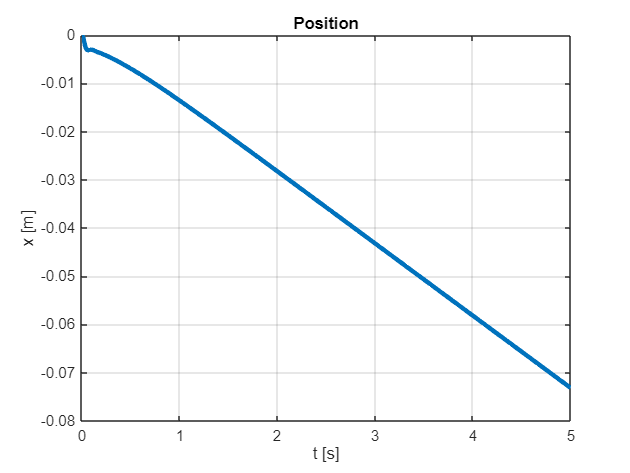

run("complete/complete_parameters.m")
% Initial state
X0 = [0; 0; -3*pi/180; 0];

Tsim = 5;
%  (vref = 0), keep stable position
t = 0:0.001:Tsim;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
theta_v = out.simout.signals.values(:,3);
dtheta_v = out.simout.signals.values(:,4);
theta_mes = out.theta_measure.signals.values();
torque_v = out.torque.signals.values();
torque2_v = out.torque_eq_2.signals.values();
domega = out.domega.signals.values();
ddx = out.ddx.signals.values(1,:);
t_v = out.tout;


% x
figure;
plot(t_v, x_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('x [m]');
title('Position');
grid on;

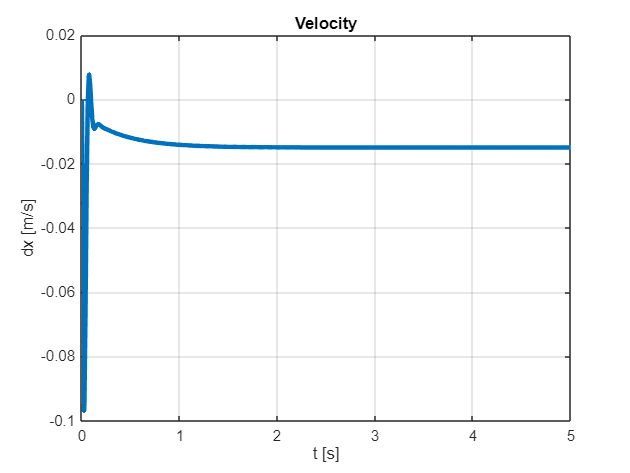


% dx
figure;
plot(t_v, dx_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
grid on;

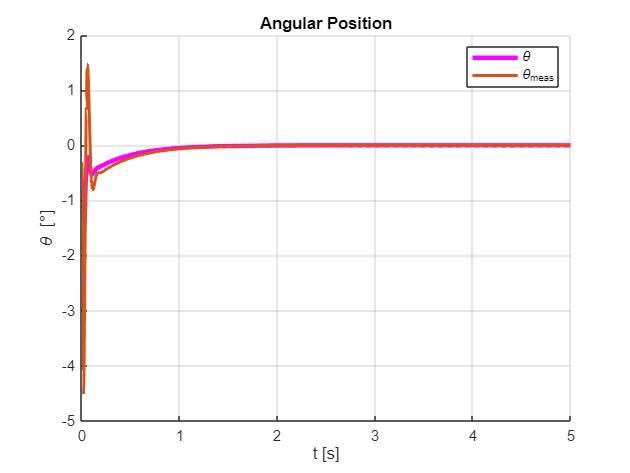


% theta
figure;
hold on;
    plot(t_v, theta_v*180/pi, "LineWidth", 3,"Color","magenta","DisplayName","\theta");

plot(t_v, theta_mes*180/pi, 'LineWidth', 2,"DisplayName","\theta_{meas}");

xlabel('t [s]');
ylabel('\theta [°]');
title('Angular Position');
legend('show');
grid on;

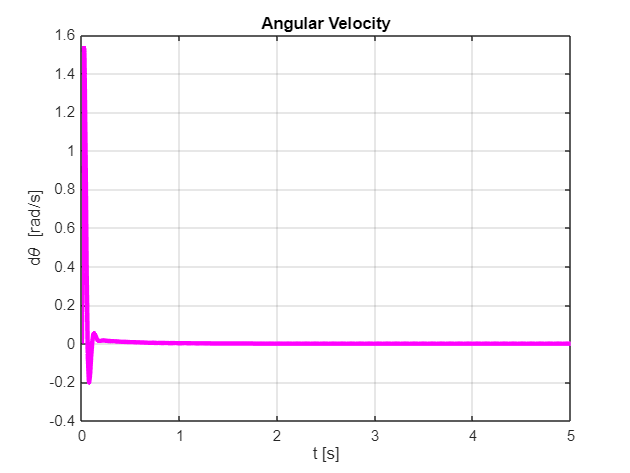


% dtheta
figure;
plot(t_v, dtheta_v, "LineWidth", 3,"Color","magenta");
xlabel('t [s]');
ylabel('d\theta [rad/s]');
title('Angular Velocity');
hold on;
grid on;

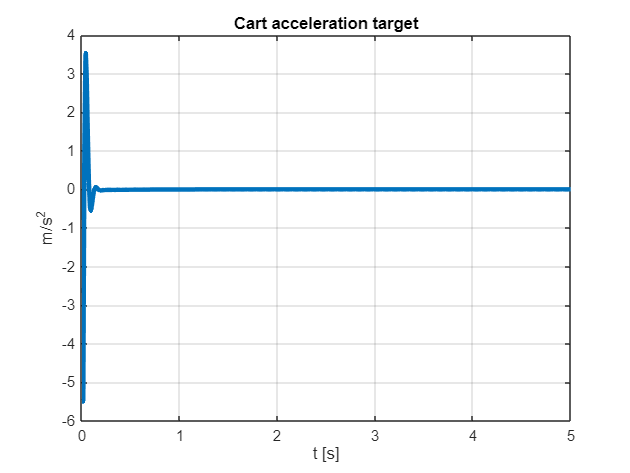


figure;
plot(t_v, domega*r, "LineWidth", 3);

xlabel('t [s]');
ylabel('m/s^2');
title('Cart acceleration target');
grid on;

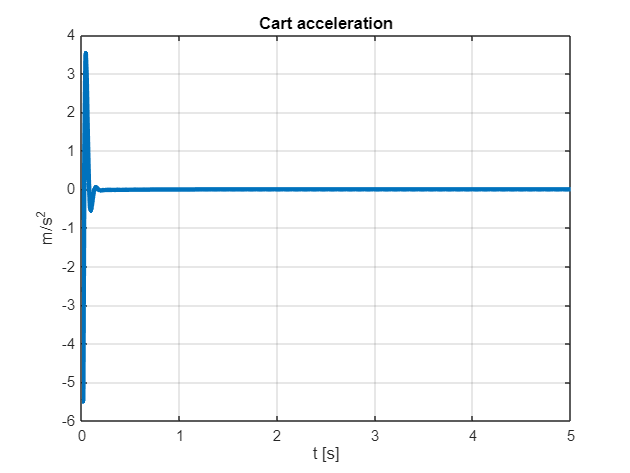


figure;
plot(t_v, ddx, "LineWidth", 3);
xlabel('t [s]');
ylabel('m/s^2');
title('Cart acceleration');
grid on;

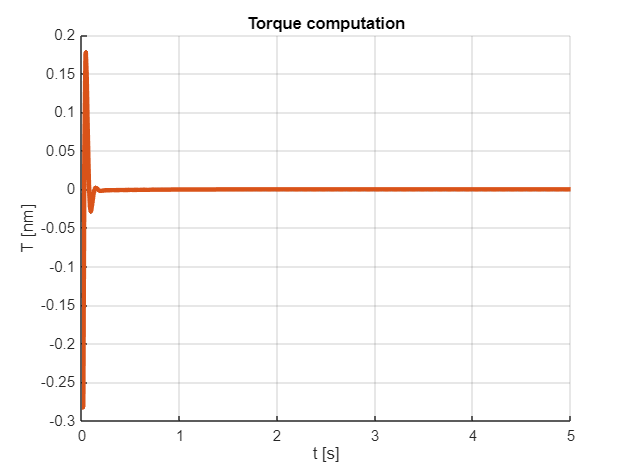


figure;
hold on;
plot(t_v, torque_v, "LineWidth", 3);
xlabel('t [s]');

plot(t_v, torque2_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('T [nm]');
title('Torque computation');
hold off;
grid on;